# **Etapa 2**

Para analizar los datos adquiridos por las antenas, primero es necesarios cargar el conjunto de datos.

filenames = dir('datos/*.txt');

#### **Visualización del demo**

Ahora visualizaremos la información proporcionada en el demo.

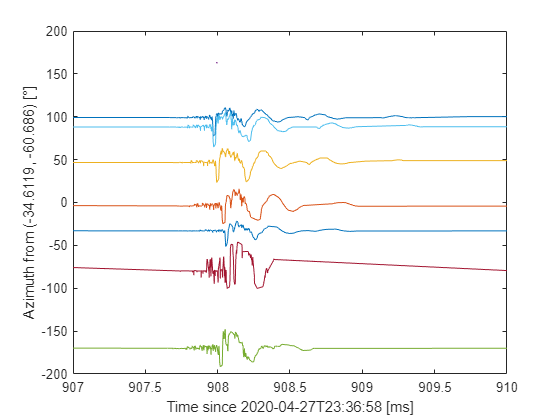

data = readtable(fullfile(filenames(1).folder, filenames(1).name));
corrected_time = table2array(data(2:end, 2));
signal = table2array(data(2:end, 4));

window = [1 1500;
    1501 2921;
    2921 4196;
    4198 4224;
    4226 6000;
    6000 7226;
    7227 8233;
    8234 9711];

figure,
for i = 1:8
    plot(corrected_time(window(i, 1):window(i, 2)), ...
        signal(window(i, 1):window(i, 2))), hold on
end
xlabel('Time since 2020-04-27T23:36:58 [ms]')
ylabel('Azimuth from (-34.6119, -60.686) [°]')
xlim([907 910])

De la figura se observa la distribución del la amplitud de la señal respecto a un breve periodo de tiempo (como se indicaba en la guía de la segunda etapa).

**Visualización de la información obtenida por las antenas**

Primero, visualizaremos la información adquirida por las antenas mediante espectogramas.

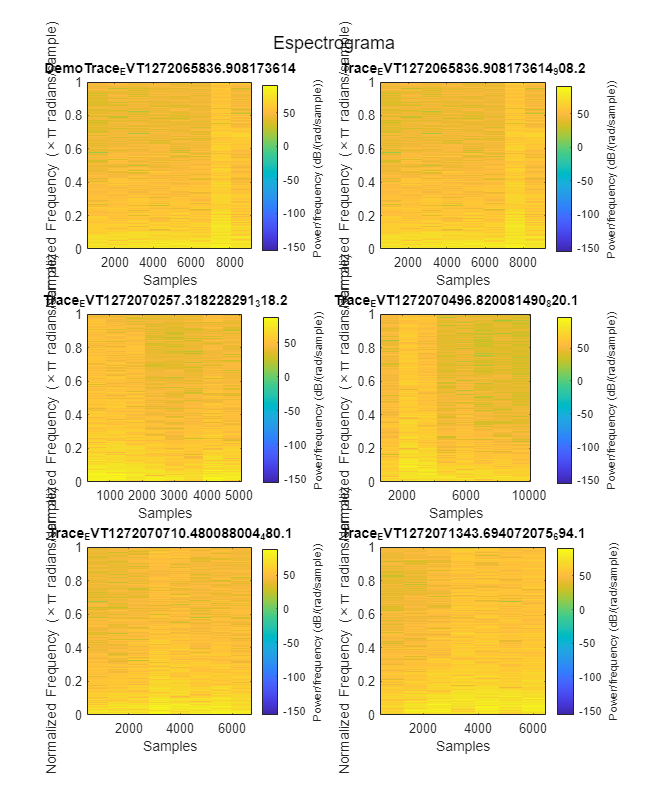

figure('Renderer', 'painters', 'Position', [0, 0, 1000 1200])
sgtitle('Espectrograma') 
for i = 1:length(filenames)
    data = readtable(fullfile(filenames(i).folder, filenames(i).name));
    signal = table2array(data(2:end, 3));

    % player = audioplayer(signal / 24000, 5000);
    % play(player)
    
    subplot(3, 2, i), spectrogram(signal, 'yaxis'), title(erase(filenames(i).name, '.txt'))

end

Lo que se observa es que la amplitud de la señal es bastante uniforme en todo el espectro de la frecuencia normalizada, lo que nos podría indicar que contiene mucho ruido o demasiada información. Para poder visualizar mejor dicha información procederemos a calcular el espectro de la potencia de cada una de las señales.

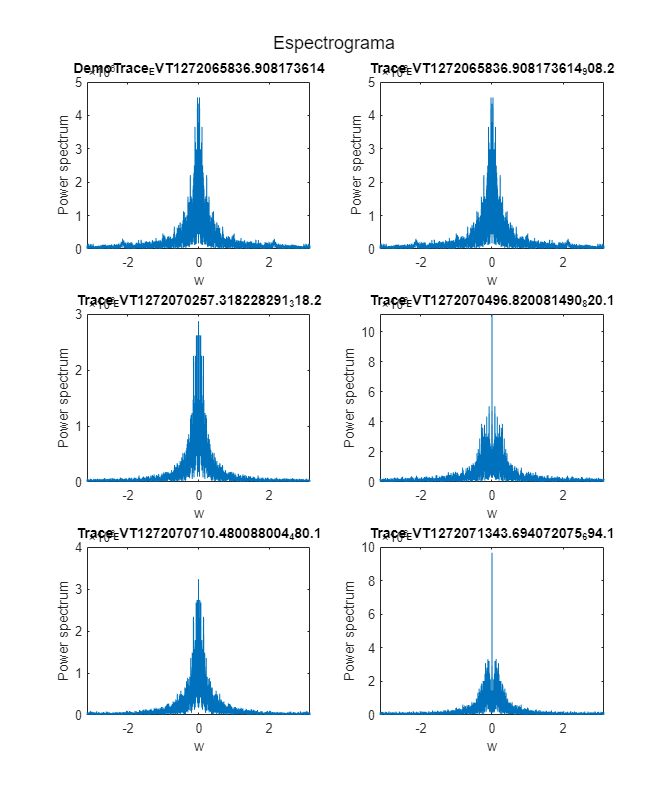

figure('Renderer', 'painters', 'Position', [0, 0, 1000 1200])
sgtitle('Especto de potencia de las señales en Fourier') 
for i = 1:length(filenames)
    data = readtable(fullfile(filenames(i).folder, filenames(i).name));
    signal = table2array(data(2:end, 3));
    
    w = linspace(-pi, pi, length(signal));
    fsignal = fftshift(fft(signal));
    subplot(3, 2, i), plot(w, abs(fsignal)), title([erase(filenames(i).name, '.txt')])
    xlabel('w'), ylabel('Power spectrum'), xlim([w(1) w(end)])

end

De esta figura se puede concluir que la mayoría de las antenas adquieren información semejante de baja frecuencia con una potencia espectral de aproximadamente $4\times {10}^6$ a excepción de dos antenas que logran obtener una potencia mucho más alta de aproximadamente $10\times {10}^6$.